tRange=[0,1.4]

tRange =          0    1.4000


Y0=[156 5.2 0 0 0 5.2 0]

Y0 =   156.0000    5.2000         0         0         0    5.2000         0


[tSol,YSol]=ode45(@neural,tRange,Y0)

tSol =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


YSol =   156.0000    5.2000         0         0         0    5.2000         0
  156.0000    5.2001    0.0000         0   -0.0000    5.1999   -0.0001
  156.0000    5.2001    0.0000         0   -0.0000    5.1999   -0.0001
  156.0000    5.2002    0.0000         0   -0.0001    5.1998   -0.0002
  156.0000    5.2002    0.0000         0   -0.0001    5.1998   -0.0002
  156.0000    5.2005    0.0000         0   -0.0002    5.1994   -0.0005
  156.0000    5.2007    0.0001         0   -0.0002    5.1991   -0.0007
  156.0000    5.2010    0.0001         0   -0.0003    5.1988   -0.0010
  156.0000    5.2012    0.0001         0   -0.0004    5.1985   -0.0012
  156.0000    5.2025    0.0002         0   -0.0008    5.1970   -0.0024



z1=YSol(:,1)

z1 =   156.0000
  156.0000
  156.0000
  156.0000
  156.0000
  156.0000
  156.0000
  156.0000
  156.0000
  156.0000


z2=YSol(:,2)

z2 =     5.2000
    5.2001
    5.2001
    5.2002
    5.2002
    5.2005
    5.2007
    5.2010
    5.2012
    5.2025


z3=YSol(:,3)

z3 =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0002


z4=YSol(:,4)

z4 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


z5=YSol(:,5)

z5 =          0
   -0.0000
   -0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0003
   -0.0004
   -0.0008


z6=YSol(:,6)

z6 =     5.2000
    5.1999
    5.1999
    5.1998
    5.1998
    5.1994
    5.1991
    5.1988
    5.1985
    5.1970


z7=YSol(:,7)

z7 =          0
   -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0005
   -0.0007
   -0.0010
   -0.0012
   -0.0024



p=1.5

p = 1.5000

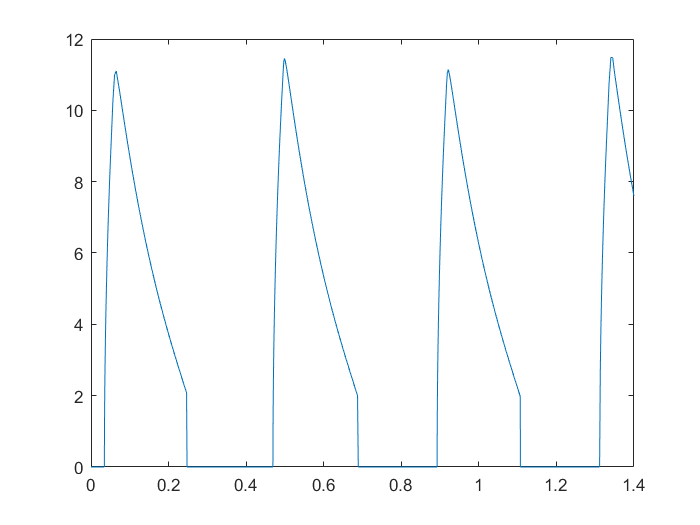

Vrest=-60;
llindar1=-50;
llindar2=-50;
llindar3=-50;
llindar4=-50;
llindar5=-50;
llindar6=-55;
llindar7=-55;

termin1=llindar1-Vrest;
termin2=llindar2-Vrest;
termin3=llindar3-Vrest;
termin4=llindar4-Vrest;
termin5=llindar5-Vrest;
termin6=llindar6-Vrest;
termin7=llindar7-Vrest;

a1=real(p.*sqrt((real(sqrt(z1)).^2).^2-termin1.^2));
a2=real(p.*sqrt((real(sqrt(z2)).^2).^2-termin2.^2));
a3=real(p.*sqrt((real(sqrt(z3)).^2).^2-termin3.^2));
a4=real(p.*sqrt((real(sqrt(z4)).^2).^2-termin4.^2));
a5=real(p.*sqrt((real(sqrt(z5)).^2).^2-termin5.^2));
a6=real(p.*sqrt((real(sqrt(z6)).^2).^2-termin6.^2));
a7=real(p.*sqrt((real(sqrt(z7)).^2).^2-termin7.^2));


plot(tSol,a2)

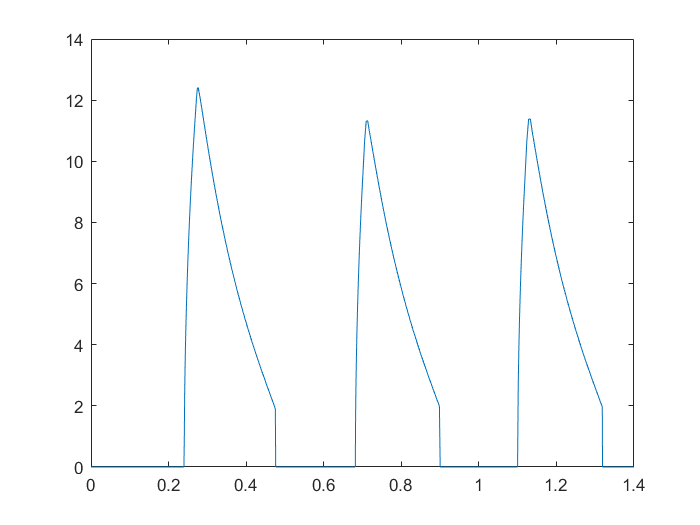

plot(tSol,a3)

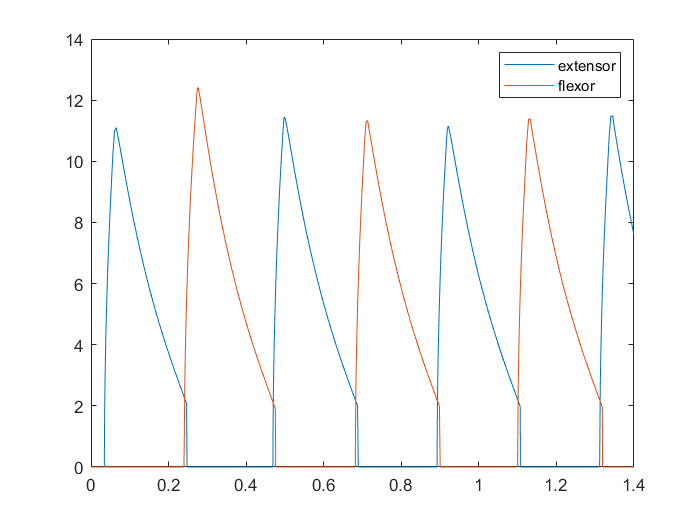


plot(tSol,a2)
hold on
plot(tSol,a3)
legend("extensor","flexor")
hold off

function dYdt=neural(~,Y)
z1=Y(1);
z2=Y(2);
z3=Y(3);
z4=Y(4);
z5=Y(5);
z6=Y(6);
z7=Y(7);

Eexc=2;
Ein=-70;
Vrest=-60;
llindar1=-50;
llindar2=-50;
llindar3=-50;
llindar4=-50;
llindar5=-50;
llindar6=-55;
llindar7=-55;

termx1=Eexc-llindar1;
termy1=llindar1-Ein;
termin1=llindar1-Vrest;
termx2=Eexc-llindar2;
termy2=llindar2-Ein;
termin2=llindar2-Vrest;
termx3=Eexc-llindar3;
termy3=llindar3-Ein;
termin3=llindar3-Vrest;
termx4=Eexc-llindar4;
termy4=llindar4-Ein;
termin4=llindar4-Vrest;
termx5=Eexc-llindar5;
termy5=llindar5-Ein;
termin5=llindar5-Vrest;
termx6=Eexc-llindar6;
termy6=llindar6-Ein;
termin6=llindar6-Vrest;
termx7=Eexc-llindar7;
termy7=llindar7-Ein;
termin7=llindar7-Vrest;

p=1.25;

a1=real(p.*sqrt((real(sqrt(z1)).^2).^2-termin1.^2));
a2=real(p.*sqrt((real(sqrt(z2)).^2).^2-termin2.^2));
a3=real(p.*sqrt((real(sqrt(z3)).^2).^2-termin3.^2));
a4=real(p.*sqrt((real(sqrt(z4)).^2).^2-termin4.^2));
a5=real(p.*sqrt((real(sqrt(z5)).^2).^2-termin5.^2));
a6=real(p.*sqrt((real(sqrt(z6)).^2).^2-termin6.^2));
a7=real(p.*sqrt((real(sqrt(z7)).^2).^2-termin7.^2));

b1=(a1.^2)./(2.83.^2+a1.^2);
b2=(a2.^2)./(2.83.^2+a2.^2);
b3=(a3.^2)./(2.83.^2+a3.^2);
b4=(a4.^2)./(2.83.^2+a4.^2);
b5=(a5.^2)./(2.83.^2+a5.^2);
b6=(a6.^2)./(2.83.^2+a6.^2);
b7=(a7.^2)./(2.83.^2+a7.^2);

B=[b1;b2;b3;b4;b5;b6;b7];

W1=termx1.*[0 0 0 0 0 0 0]-termy1.*[0 0 0 0 0 0 0];
W2=termx2.*[0.35 0 0 0 0 0 0]-termy2.*[0 0 0 0.42 0 0 3];
W3=termx3.*[0.35 0 0 0 0 0 0]-termy3.*[0 0 0 0 0.42 3 0];
W4=termx4.*[0 1 0 0 0 0 0]-termy4.*[0 0 0 0 0 0 1];
W5=termx5.*[0 0 1 0 0 0 0]-termy5.*[0 0 0 0 0 1 0];
W6=termx6.*[0 0.68 0 0 0 0 0]-termy6.*[0 0 0 2 0 0 1];
W7=termx7.*[0 0 0.68 0 0 0 0]-termy7.*[0 0 0 0 2 1 0];

tao1=1000;
tao2=0.075;
tao3=0.075;
tao4=0.1;
tao5=0.1;
tao6=0.025;
tao7=0.025;

dz1dt=(1/tao1).*(-z1+W1*B);
dz2dt=(1/tao2).*(-z2+W2*B);
dz3dt=(1/tao3).*(-z3+W3*B);
dz4dt=(1/tao4).*(-z4+W4*B);
dz5dt=(1/tao5).*(-z5+W5*B);
dz6dt=(1/tao6).*(-z6+W6*B);
dz7dt=(1/tao7).*(-z7+W7*B);

dYdt=[dz1dt;dz2dt;dz3dt;dz4dt;dz5dt;dz6dt;dz7dt];

end
